# Reglertuning

This script evaluates the error of refrence position (from Trajectory) and actual observed position for various Controllerparameters.

clear all, close all, clc;

## Constants


%Kreisfahrt 103.3864ms  Sinusfahrt 160.3870ms   WallCrash 106ms --> Mean
%123.2578ms (61cycles) (cycle time: 2 ms)
anzahlMessungen =20;
    avgErrX = zeros(anzahlMessungen,1);
    avgErrY =zeros(anzahlMessungen,1);
    avgErrTheta =zeros(anzahlMessungen,1);
    
    varX = zeros(anzahlMessungen,1);
    varY = zeros(anzahlMessungen,1);
    varTheta = zeros(anzahlMessungen,1);
    
    gainX = zeros(anzahlMessungen,1);
    gainY = zeros(anzahlMessungen,1);
    gainTheta = zeros(anzahlMessungen,1);

## Set up the Import Options and import the data

for k=1:1:20
    filename = sprintf('%s_%d','tuning2',k)
    % Import the data
    data = readtable(filename);
    if (k ~= 2) && (k ~= 15)
        % Trim data
        enableRobot = data.enableRobot;
        yBoArrivedAtDestination = data.yBoArrivedAtDestination;
        FIRST_SAMPLE_IDX = find(enableRobot, 1, "first")+2;  %+2 da sonst trajektorie noch nicht ref pos verfügbar
        LAST_SAMPLE_IDX = find(yBoArrivedAtDestination, 1, "first");
        
        data = data(FIRST_SAMPLE_IDX:LAST_SAMPLE_IDX,:);
        
        % Convert to output type
        t = data.Name / 1000;       % ms -> s
        t = t - t(1);           % ensure t(0) = 0 s
        
        % read pose data
        xRef = data.xRef;
        xCam = data.xCam;
        xObs = data.xObs;
        xKalman = data.xKalman;
        yRef = data.yRef;
        yCam = data.yCam;
        yObs = data.yObs;
        yKalman = data.yKalman;
        thetaRef = data.thetaRef;
        thetaCam = data.thetaCam;
        thetaObs = data.thetaObs;
        thetaKalman = data.thetaKalman;

filename = 'tuning2_1'

filename = 'tuning2_2'

filename = 'tuning2_3'

filename = 'tuning2_4'

filename = 'tuning2_5'

filename = 'tuning2_6'

filename = 'tuning2_7'

filename = 'tuning2_8'

filename = 'tuning2_9'

filename = 'tuning2_10'

filename = 'tuning2_11'

filename = 'tuning2_12'

filename = 'tuning2_13'

filename = 'tuning2_14'

filename = 'tuning2_15'

filename = 'tuning2_16'

filename = 'tuning2_17'

filename = 'tuning2_18'

filename = 'tuning2_19'

filename = 'tuning2_20'

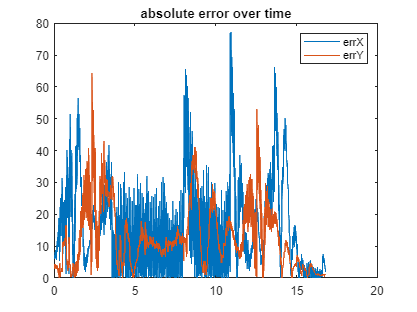

        % plot XY
        plot(xRef, yRef, xCam, yCam, xObs, yObs, xKalman, yKalman);
        title("XY Plot");
        legend("Ref", "Cam", "Luenberger", "Kalman");
        xlim([254 5510])
        ylim([2176 2930])
        legend('Location',"best")
        xlabel("x [mm]")
        ylabel("y [mm]")
        
        % plot x = f(t)
        plot(t, xRef, t, xKalman);
        title("x = f(t)");
        xlabel("t / ms");
        
        % plot x = f(t) mit simple obs
        plot(t, xRef, t, xObs, t, xKalman);
        title("x = f(t)");
        xlabel("t / ms");
        
        
        % plot y = f(t)
        plot(t, yRef, t, yKalman);
        title("y = f(t)");
        xlabel("t / ms");
        ylim([0, 6000]);
        
        
        sseX = zeros(1,length(xRef));
        for i = [1 : length(xRef)]
            % calculate absolute error in each axis 
            seX(i) = (xRef(i)-xKalman(i))^2;
            seY(i) = (yRef(i)-yKalman(i))^2;
            seTheta(i) = (thetaRef(i)-thetaKalman(i))^2;
            sseX(i) = sum(seX);
            sseY(i) = sum(seY);
            sseTheta(i) = sum(seTheta);
        end
        
        % plot results
        plot(t, sqrt(seX), t, sqrt(seY));

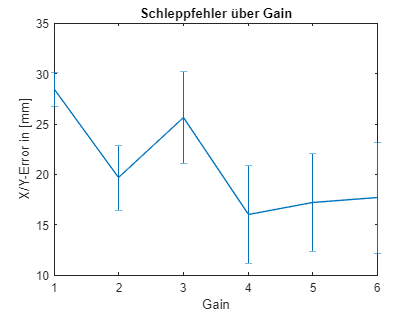

        title("absolute error over time");
        legend("errX", "errY");
        
        
        % plot(t, sseX);
        % title("Sum of squared error over time in X");
        % xlabel("time [s]")
        % ylabel("SSE in X [mm^2]");
        
        
        avgErrX(k) = mean(sqrt(seX));
        avgErrY(k) = mean(sqrt(seY));
        avgErrTheta(k) = mean(sqrt(seTheta));
        
        varX(k) = sqrt(var(sqrt(seX)));
        varY(k) = sqrt(var(sqrt(seY)));
        varTheta(k) = sqrt(var(sqrt(seTheta)));
        
        gainX(k) = data.controllerKX(1);
        gainY(k) = data.controllerKY(1);
        gainTheta(k) = data.controllerKTheta(1);
    end
    clearvars -except   gainTheta gainY gainX varTheta varY varX   avgErrTheta avgErrY avgErrX 
end

%delete messung 2 und 15
outliers = [2,15];
avgErrX(outliers) = [];
avgErrY(outliers) = [];
avgErrTheta(outliers) = [];

varX(outliers) = [];
varY(outliers) = [];
varTheta(outliers) = [];

gainX(outliers) = [];
gainY(outliers) = [];
gainTheta(outliers) = [];







% Calculate variance and mean of error for every Gain
meanErrXY = zeros(6,1);
varErrXY = zeros(6,1);
meanErrTheta = zeros(6,1);
varErrTheta = zeros(6,1);
for gain=1:1:6
    meanErrXY(gain) = mean([avgErrX(gainX==gain); avgErrY(gainY==gain)]);
    varErrXY(gain) = var([avgErrX(gainX==gain); avgErrY(gainY==gain)]);

    meanErrTheta(gain) = mean(avgErrTheta(gainTheta==gain));
    varErrTheta(gain) = var(avgErrTheta(gainTheta==gain));
end



errorbar(1:1:6, meanErrXY, sqrt(varErrXY))
title("Schleppfehler über Gain")
xlabel("Gain")
ylabel("X/Y-Error in [mm]")









% mrsX = sqrt(sseX(end))/length(sseX)           % error per sample in mm
% mrsY = sqrt(sseY(end))/length(sseY)
% mrsTheta = sqrt(sseTheta(end))/length(sseTheta)


